function [new_pos, new_vel] = step_drone(pos, vel, input)
    noisy_input = input * (1+0*randn());
    if (noisy_input < 0), noisy_input = 0; end
    new_vel = (4*1e-5*noisy_input*noisy_input-9.81)*.001 + vel;
    % Average out the velocity since if we assume 
    new_pos = pos + (new_vel+vel)*0.0005; 
end

Beign by dropping the drone from an initial height to make sure the step function is working

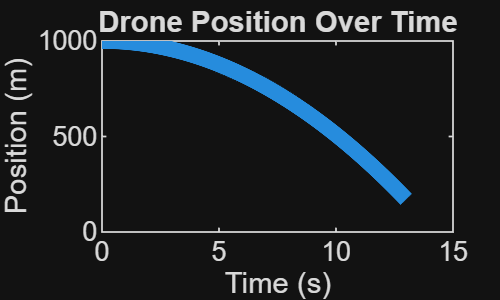

% Start with a test of defining the initial position of the
% drone at 1km and step the controller for 1s (1000 times)

initialPos = 1e3; % Initial position in km
initialVel = 0; % Initial velocity in m/s
input = 0; % Example input for the controller

sample_freq = 0.001;
time_to_run_sim = 13; % The time to run is in seconds
number_of_samples = time_to_run_sim/sample_freq+1;

drone_positions = zeros(number_of_samples, 1);
drone_velocities = zeros(number_of_samples, 1);
timestamps = linspace(0, time_to_run_sim, number_of_samples);

drone_positions(1) = initialPos; 
drone_velocities(1) = initialVel;

for i = 1:number_of_samples-1
    [drone_positions(i+1), drone_velocities(i+1)] = step_drone(drone_positions(i), drone_velocities(i), input);
end

% Plot the drone positions over time
plot(timestamps, drone_positions, 'LineWidth', 5);

xlabel('Time (s)');
ylabel('Position (m)');
title('Drone Position Over Time');

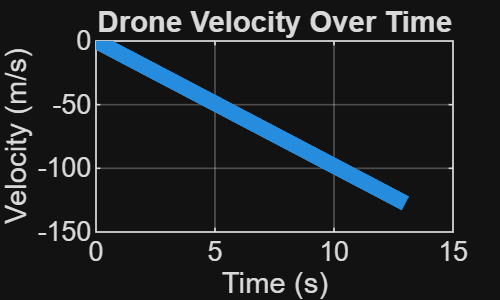



% Plot the drone velocity over time
figure; % Create a new figure for the velocity plot
plot(timestamps, drone_velocities, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Drone Velocity Over Time');
grid on;

Now apply a very simple control law of input = 495 - (error)

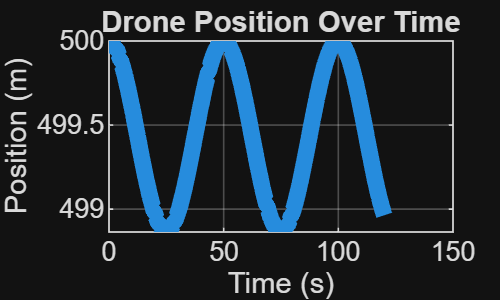

% Run a test with the simple control law

initialPos = 500; % Initial position in km
target = 500;
initialVel = 0; % Initial velocity in m/s

K = 0.4;

sample_freq = 0.001;
time_to_run_sim = 120; % The time to run is in seconds
number_of_samples = time_to_run_sim/sample_freq+1;

drone_positions = zeros(number_of_samples, 1);
drone_velocities = zeros(number_of_samples, 1);
timestamps = linspace(0, time_to_run_sim, number_of_samples);

drone_positions(1) = initialPos; 
drone_velocities(1) = initialVel;

for i = 1:number_of_samples-1
    input = 495 + K*(target - drone_positions(i)); % Update input based on the target position
    [drone_positions(i+1), drone_velocities(i+1)] = step_drone(drone_positions(i), drone_velocities(i), input);
end

% Plot the drone positions over time
plot(timestamps, drone_positions, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Position (m)');
title('Drone Position Over Time');
grid on;

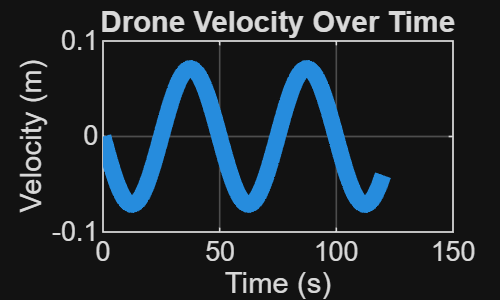


% Plot the drone positions over time
plot(timestamps, drone_velocities, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Velocity (m)');
title('Drone Velocity Over Time');
grid on;

Now, we will generate the error transfer function assuming no feedbacl.

As derived in the pdf the system transfer function is $\frac{1}{s^2}
$.  Below we find this root locus

r = 1000

r = 1000

no_control_error_num = [1000 0 0];
no_control_error_denom = [1 0 0.56]

no_control_error_denom =     1.0000         0    0.5600


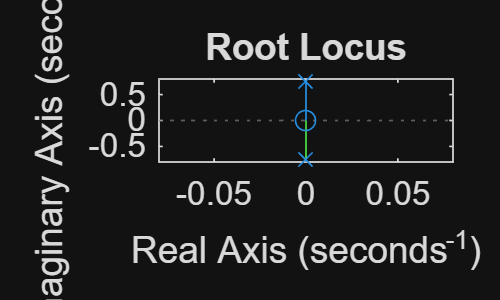

closed_loop_error_no_control = tf(no_control_error_num, no_control_error_denom);
rlocus(closed_loop_error_no_control);

As seen both poles have 0 real components with imaginary components meaning the system is not dampened and will keep oscillating.  Thus, we apply a control law as noted in the design document to move these poles onto the negative real axis.  This means we define a law $G(s) = \frac{z_1+s}{a_1s^3 +a_2s^2 +a_3s+a_4$ where each of the values were calculated separately and listed below.

syms s;
desired_poly = expand((s+0.4+0.01*j)*(s+0.4-0.01*j)*(s+0.01+0.005*j)*(s+0.01-0.005*j)*(s+1))

$$desired\_poly = s^{5}+\frac{91\,s^{4}}{50}+\frac{39849\,s^{3}}{40000}+\frac{179527\,s^{2}}{1000000}+\frac{265761\,s}{80000000}+\frac{1601}{80000000}$$


coeffs = sym2poly(desired_poly);

desired_poly = desired_poly/(coeffs(5))*0.08;

coeffs = sym2poly(desired_poly)

coeffs =    24.0818   43.8289   23.9909    4.3233    0.0800    0.0005



% Define the coefficients for the controlled system
a1 = coeffs(1);
a2 = coeffs(2);
a3 = coeffs(3);
a4 = coeffs(4);
z1 = coeffs(6)/0.08;

Now we do out the math in the design document to get the following equation for our closed-loop, closed-control transfer function.  The root locus will also be generated.

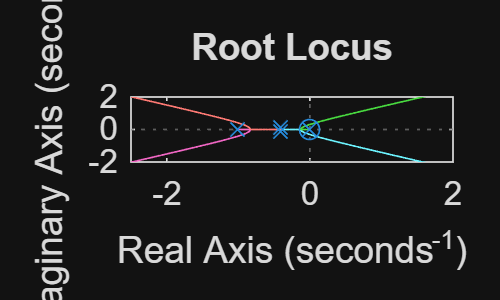

controlled_num = [a1, a2, a3, a4, 0, 0];
controlled_denom = [a1, a2, a3, a4, 0.08, 0.08*z1];
controlled_sys = tf(controlled_num, controlled_denom);


output_tf = 0.05*tf([0.08*z1, 0.08], [a1, a2, a3, a4, 0.08, 0.08*z1]);


% Find the root locus of the open loop tf G(s)H(s)
open_loop_tf = 0.05*tf([0.08, 0.08*z1], [a1, a2, a3, a4, 0, 0]);
rlocus(open_loop_tf);

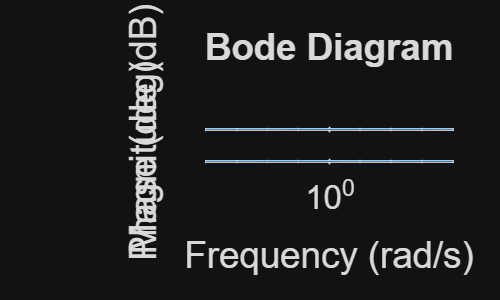


% Generate the bode plot of the closed loop transfer function with the gain
% and phase on the same plot
bode(output_tf);

Now, we just need to realize the G(s) which produces the desired transfer function giving us the desired root locus.  As we can see, with a small enough gain we can achieve a system with all poles left of the real axis and some poles having small imaginary components.  (Little Oscillation).

syms s;
Gtf = 0.1*tf([1, z1], [a1, a2, a3, a4]);


discrete_system = c2d(Gtf, 0.001, 'tustin')


discrete_system =
 
  1.037e-09 z^3 + 1.037e-09 z^2 - 1.037e-09 z - 1.037e-09
  -------------------------------------------------------
            z^3 - 2.998 z^2 + 2.996 z - 0.9982
 
Sample time: 0.001 seconds
Discrete-time transfer function.



% Get the numerator and denominator vectors from the discrete system
[num_coeffs, denom_coeffs] = tfdata(discrete_system, 'v');

disc_roots = roots(denom_coeffs)

disc_roots =    0.9996 + 0.0001i
   0.9996 - 0.0001i
   0.9990 + 0.0000i


abs(disc_roots)

ans =     0.9996
    0.9996
    0.9990


denom_coeffs = denom_coeffs(2:end);


This discrete time tf allows us to achieve a needed different equation.

Using our different equation we can find the output using a control law

function system_input = Gpole_placement_control_law(errors, system_inputs, num_coeffs, denom_coeffs, n)
    x_order = length(num_coeffs);
    y_order = length(denom_coeffs);

    x_prod = dot(flip(errors(n-x_order+1:n)), num_coeffs);

    y_prod = dot(flip(system_inputs(n-y_order:n-1)), denom_coeffs);

    system_input = x_prod - y_prod; % Calculate the control output based on the difference
end


Now, reapply the test but with our control law.

% Run a test with the simple control law

initialPos = 500; % Initial position in km
target = 900;
initialVel = 0; % Initial velocity in m/s


sample_freq = 0.001;
time_to_run_sim = 160; % The time to run is in seconds
number_of_samples = time_to_run_sim/sample_freq+1;

drone_positions = zeros(number_of_samples, 1);
drone_velocities = zeros(number_of_samples, 1);
timestamps = linspace(0, time_to_run_sim, number_of_samples);

drone_errors = zeros(number_of_samples, 1);
drone_inputs = zeros(number_of_samples, 1);

drone_positions(4) = initialPos; 
drone_velocities(4) = initialVel;

for i = 4:number_of_samples-1
    drone_errors(i) = target - drone_positions(i);
    drone_inputs(i) = Gpole_placement_control_law(drone_errors, drone_inputs, num_coeffs, denom_coeffs, i);
    [drone_positions(i+1), drone_velocities(i+1)] = step_drone(drone_positions(i), drone_velocities(i), drone_inputs(i)+495);
end

drone_inputs

drone_inputs =          0
         0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001


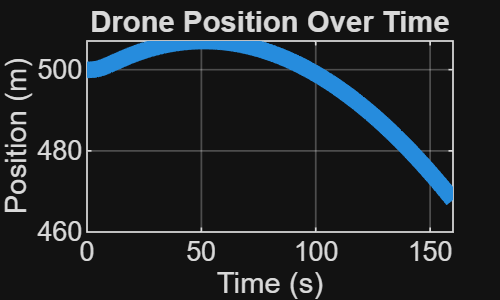


% Plot the drone positions over time
plot(timestamps(4:end), drone_positions(4:end), 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Position (m)');
title('Drone Position Over Time');
grid on;

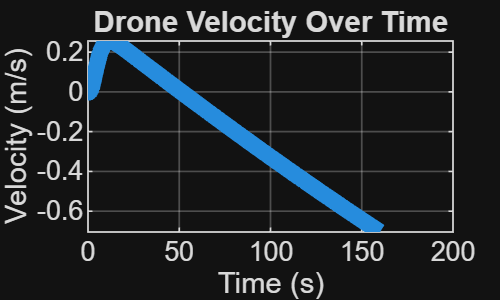


% Plot the drone positions over time
plot(timestamps, drone_velocities, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Drone Velocity Over Time');
grid on;

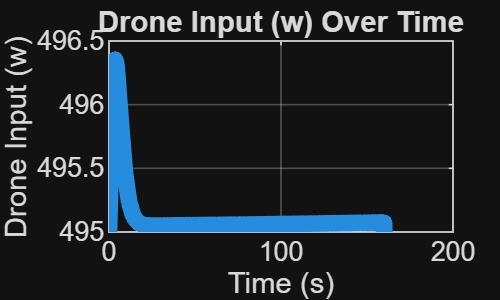


% Plot the drone inputs over time
plot(timestamps, drone_inputs+495, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Drone Input (w)');
title('Drone Input (w) Over Time');
grid on;

## Now lets try a pole placement control law

In this case u (our input) is equal to v - Kx where $K=\left\lbrack 0\;k\right\rbrack$.  This is done since only the position is observable.  We could design an observer but lets see what happens with just our normal measurement at first.  In this case the poles for our system are,

(A - BK) = $\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 0
\end{array}\right\rbrack -\;\left\lbrack \begin{array}{cc}
0 & 0\ldotp 08k\\
0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -0\ldotp 08k\\
1 & 0
\end{array}\right\rbrack$

The characteristic polynomial for this matrix is the following,


$$\lambda^2 + 0.08k =0$$


We find the eignenvalues for this matrix are $\pm \sqrt {-0.08
k$

With this equation we will always have at least 1 pole with a positive real component.  This means the system will not be stable.

So we will need an observer in order to perform this full state feedback.

For our observer we say that the poles are the eigenvalues of $A - LC
$.  Supposing $L=\left\lbrack \begin{array}{c}
l_1 \\
l_2 
\end{array}\right\rbrack$.  This gives us the matrix $\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
0 & l_1 \\
0 & l_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & -l_1 \\
1 & -l_2 
\end{array}\right\rbrack$.

The characteristic polynomial of this matrix is,

$\lambda^2 +l_2 \lambda +l_1 =0$.  Which gives observer poles of 

$\frac{-l_2 \pm \sqrt{l_2^2 +4l_1 }}{2}$.  While these poles dont matter too much we will want to at least play around with them.

This allows us to use both stats in our feedback system giving us the following matrix for the new full state feedback.

(A-BK) = $\left\lbrack \begin{array}{cc}
-0\ldotp 08k_1  & -0\ldotp 08k_2 \\
1 & 0
\end{array}\right\rbrack$ giving the char poly of $\lambda^2 +0\ldotp 08\lambda +0\ldotp 08\lambda_2$

And this gives us the poles,


$$\lambda =\frac{-0\ldotp 08k_1 \pm \sqrt{{\left(0\ldotp 08k_1 \right)}^2 -4*0\ldotp 08k_2 }}{2}$$


function state_est = observe_states(A, B, C, D, y, L, prev_est, input)
    state_est = A*prev_est + L*(y - C*prev_est - D*input) + B*input;
end

function new_input = state_fbk_controller(reference, K, state)
    state_minus_ref = state;
    state_minus_ref(2) = state_minus_ref(2)-reference;
    new_input = -1* K*state_minus_ref;
end

% Find L and K based on desired observer and controller poles

desired_oberserver_poles = [-0.05+2*j, -0.05-2*j];

l2 = (-1*(desired_oberserver_poles(1) + desired_oberserver_poles(2))/0.08);
l1 = (desired_oberserver_poles(1)*desired_oberserver_poles(2));

desired_controller_poles = [-0.1-0.05j, -0.1+0.05j];

k1 = (-1*(desired_controller_poles(1) + desired_controller_poles(2))/0.08);
k2 = ((desired_controller_poles(1)*desired_controller_poles(2))/0.08);

L = [l1; l2]

L =     4.0025
    1.2500


K = [k1 k2]

K =     2.5000    0.1563


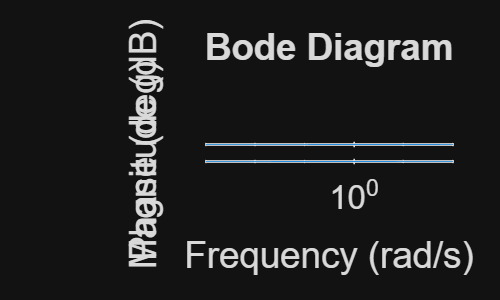


continuous_A = [0 0; 1 0];
continuous_B = [1; 0];
continuous_C = [0 1];
continuous_D = 0;

% Get the discretized state space
sysc = ss(continuous_A, continuous_B, ...
    continuous_C, continuous_D); % Create continuous system object

% 2. Define sampling time (in seconds)
Ts = 0.001;

% 3. Discretize the model using Zero-Order Hold (ZOH)
sysd = c2d(sysc, Ts, 'tustin');

% 4. Extract new discrete-time matrices
[discrete_A, discrete_B, discrete_C, discrete_D] = ssdata(sysd);

eig(discrete_A - discrete_B * K);

% Get the bode plot of this system
closed_loop_system = ss(continuous_A-continuous_B*K, continuous_B, continuous_C, continuous_D);
disc_closed_loop_sys = c2d(sysc, Ts, 'tustin');

bode(closed_loop_system);

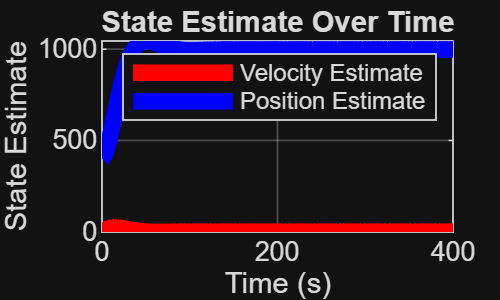

% Run a test with full state feedback

initialPos = 400; % Initial position in km
target = 1000;
initialVel = 0; % Initial velocity in m/s


sample_freq = 0.001;
time_to_run_sim = 400; % The time to run is in seconds
number_of_samples = time_to_run_sim/sample_freq+1;

drone_positions = zeros(number_of_samples, 1);
drone_velocities = zeros(number_of_samples, 1);
timestamps = linspace(0, time_to_run_sim, number_of_samples);

drone_errors = zeros(number_of_samples, 1);
drone_inputs = zeros(number_of_samples, 1);

drone_positions(4) = initialPos; 
drone_velocities(4) = initialVel;

state_est = zeros(2, number_of_samples-1);
state_est(:, 3) = [initialVel; initialPos];


for i = 4:number_of_samples-1
    
    state_est(:, i) = observe_states(discrete_A, discrete_B, ...
        discrete_C, discrete_D, drone_positions(i), L,  ...
        state_est(:, i-1), drone_inputs(i));
    drone_inputs(i) = state_fbk_controller(target, K, state_est(:, i));

    [drone_positions(i+1), drone_velocities(i+1)] = step_drone(drone_positions(i), drone_velocities(i), drone_inputs(i)+495);
end

% Plot the state estimate over time
figure;
plot(timestamps(3:number_of_samples-1), state_est(1, 3:end), 'r', timestamps(3:number_of_samples-1), state_est(2, 3:end), 'b', ...
    'LineWidth', 5);
xlabel('Time (s)');
ylabel('State Estimate');
title('State Estimate Over Time');
legend('Velocity Estimate', 'Position Estimate');
grid on;

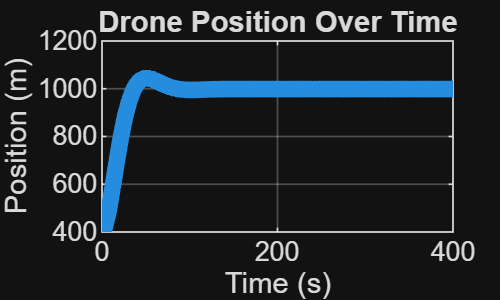


% Plot the drone positions over time
plot(timestamps(4:end), drone_positions(4:end), 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Position (m)');
title('Drone Position Over Time');
grid on;

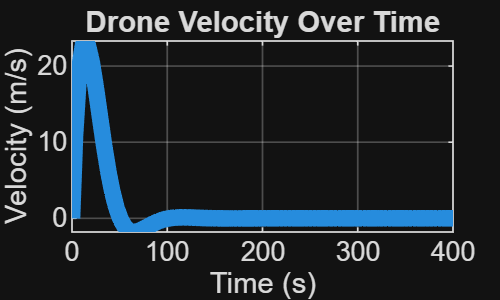


% Plot the drone positions over time
plot(timestamps, drone_velocities, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Drone Velocity Over Time');
grid on;

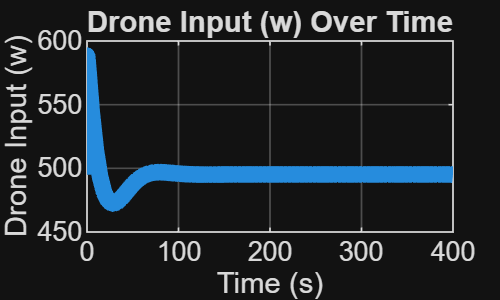


% Plot the drone inputs over time
plot(timestamps, drone_inputs+495, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Drone Input (w)');
title('Drone Input (w) Over Time');
grid on;

## Finally, lets run a simple PID controller

function [input, new_integral] = PID_control(kp, ki, kd, integral, errors, i)
    new_integral = integral + ki*errors(i);
    input = kp*errors(i) - kd*(errors(i)-errors(i-1)) + new_integral;
end

kp = 10;
ki = 5;
kd = 0.5;

system_tf = tf([1], [1, 0, 0]);
disc_pid = pid(kp, ki, kd, 0.001);

open_loop = series(disc_pid, system_tf)


open_loop =
 
  510 s^2 + 10005 s + 5000
  ------------------------
       s^4 + 1000 s^3
 
Continuous-time transfer function.


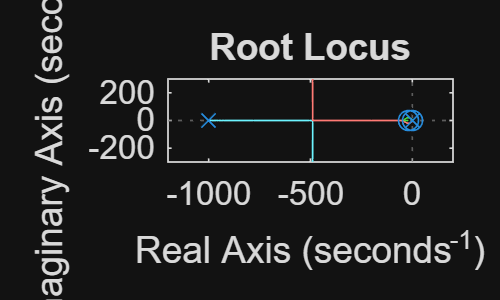


rlocus(open_loop);

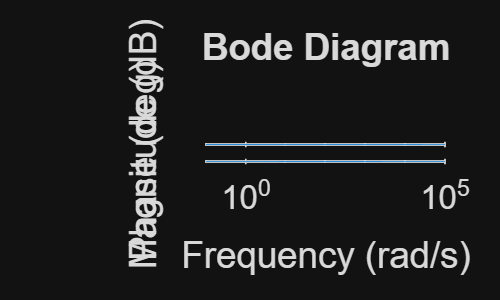


bode(feedback(open_loop, 1));

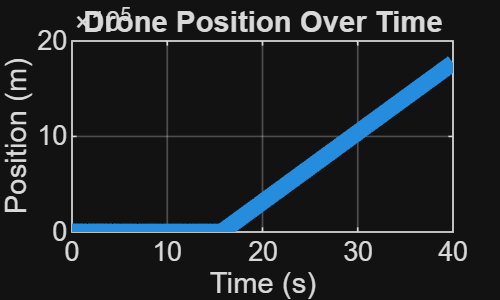

% Run a test with PID contorl law

initialPos = 500; % Initial position in km
target = 100;
initialVel = 0; % Initial velocity in m/s


sample_freq = 0.001;
time_to_run_sim = 40; % The time to run is in seconds
number_of_samples = time_to_run_sim/sample_freq+1;

drone_positions = zeros(number_of_samples, 1);
drone_velocities = zeros(number_of_samples, 1);
timestamps = linspace(0, time_to_run_sim, number_of_samples);

drone_errors = zeros(number_of_samples, 1);
drone_inputs = zeros(number_of_samples, 1);

drone_positions(4) = initialPos; 
drone_velocities(4) = initialVel;

stored_integral = 0;

for i = 4:number_of_samples-1
    drone_errors(i) = target - drone_positions(i);
    [drone_inputs(i), stored_integral] = PID_control(kp, ki, kd, stored_integral, drone_errors, i);
    [drone_positions(i+1), drone_velocities(i+1)] = step_drone(drone_positions(i), drone_velocities(i), drone_inputs(i)+495);
end

drone_inputs;

% Plot the drone positions over time
plot(timestamps(4:end), drone_positions(4:end), 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Position (m)');
title('Drone Position Over Time');
grid on;

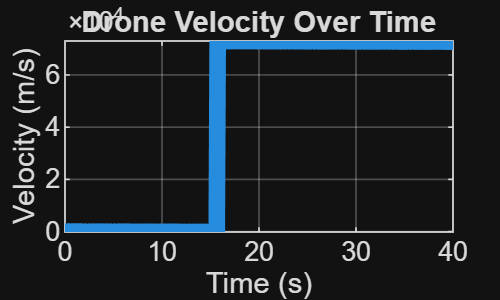


% Plot the drone positions over time
plot(timestamps, drone_velocities, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Drone Velocity Over Time');
grid on;

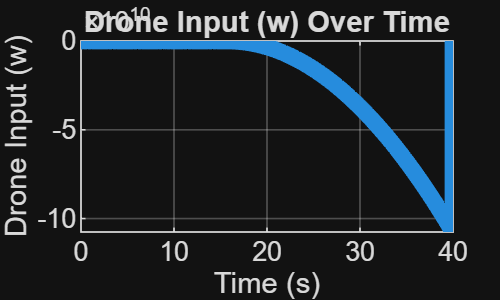


% Plot the drone inputs over time
plot(timestamps, drone_inputs+350, 'LineWidth', 5);
xlabel('Time (s)');
ylabel('Drone Input (w)');
title('Drone Input (w) Over Time');
grid on;